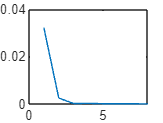

data = f(0.38);%generated data
max = 1;
min = 0;
b = (max + 0.25)/2;%0.25 represents a
count = 1;
error = 0:1:10;
error(1:10) = 0;

while (abs(f(b) - data) > 0.000001)%while data is not equal to integral
   if (f(b) > data)
       max = b;
       b = (b+min)/2; %if integral is too large, shrink b
   elseif (f(b) < data)
       min = b;
       b = (max+b)/2; %otherwise make b bigger
   error(count) = abs(f(b) - data);
   count = count + 1;
   end
end

set = 1:1:count+2;
plot(1:8, error(1:8));

disp("B was found to be: " + b);

B was found to be: 0.38
